# Optimize Buying-low Selling-high Strategy on the real stock

## Yida Chen

### Local Optimization using Real Stock Price

### With different update strategy

clf;
N_T = 2000

N_T = 2000

real_stock_price = readmatrix("stock_prices\INTC_18_21.csv", 'Range', 'E2:E988');
T = length(real_stock_price) - 1

T = 986

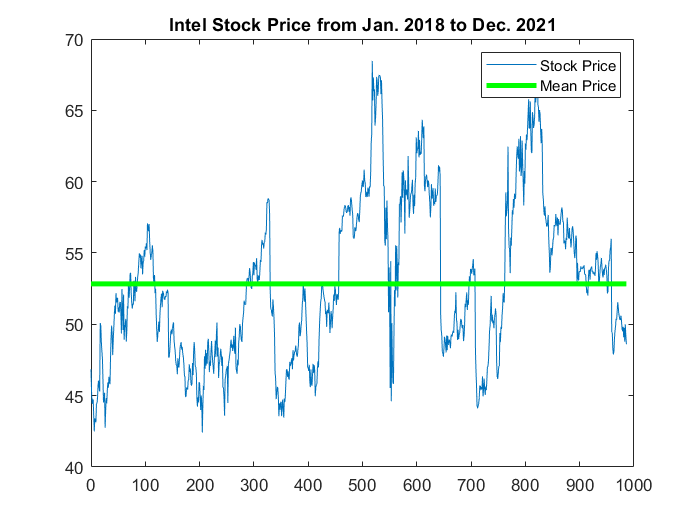

% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3)
title("Intel Stock Price from Jan. 2018 to Dec. 2021")
legend("Stock Price", "Mean Price")
hold off

clf;
N_T = 2000

N_T = 2000

real_stock_price = readmatrix("stock_prices\INTC_18_21", 'Range', 'E2:E201');
real_stock_price

real_stock_price =    46.8500
   45.2600
   44.4300
   44.7400
   44.7400
   43.6200
   42.5000
   43.4100
   43.2400
   43.1400


T = length(real_stock_price) - 1

T = 199

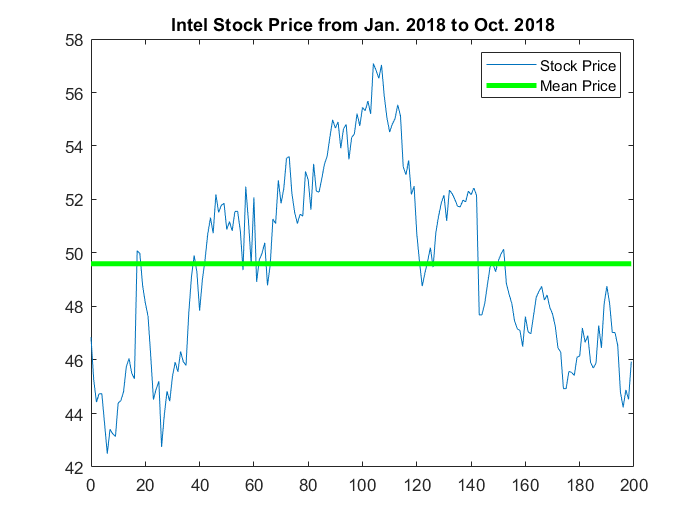

% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3)
title("Intel Stock Price from Jan. 2018 to Oct. 2018")
legend("Stock Price", "Mean Price")
hold off

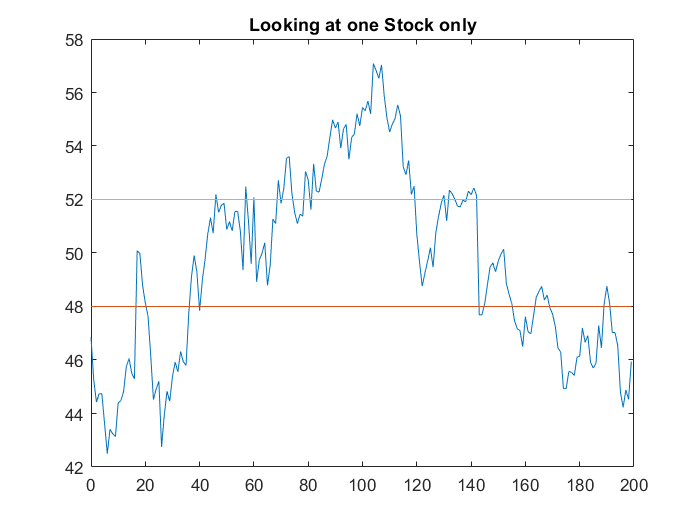

b0 = 48;
s0 = 52;
num_iter = 500;

% stock_price = stock_prices(:, randi(NSample));
t = times;
stock_price = real_stock_price;
clf;
plot(t, stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)
title("Looking at one Stock only")
hold off

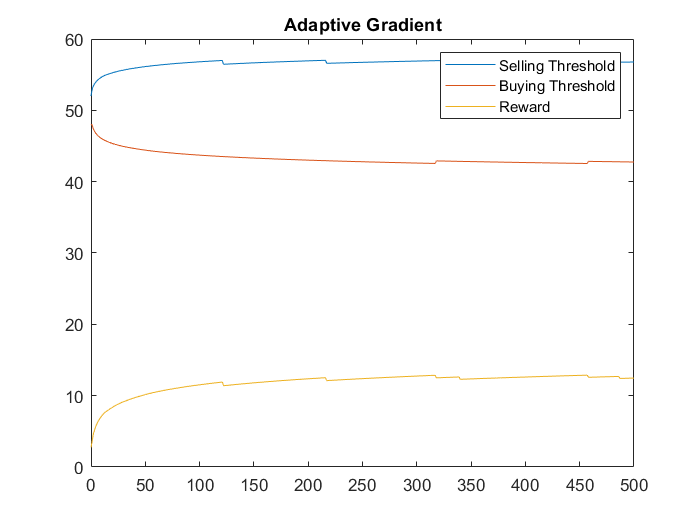

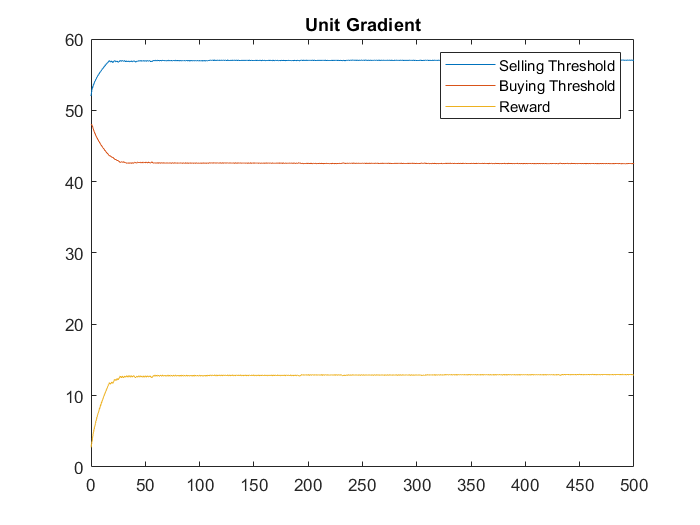

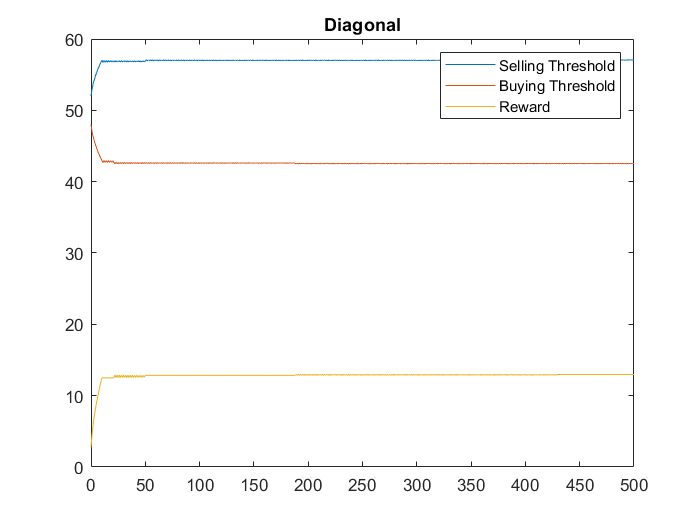

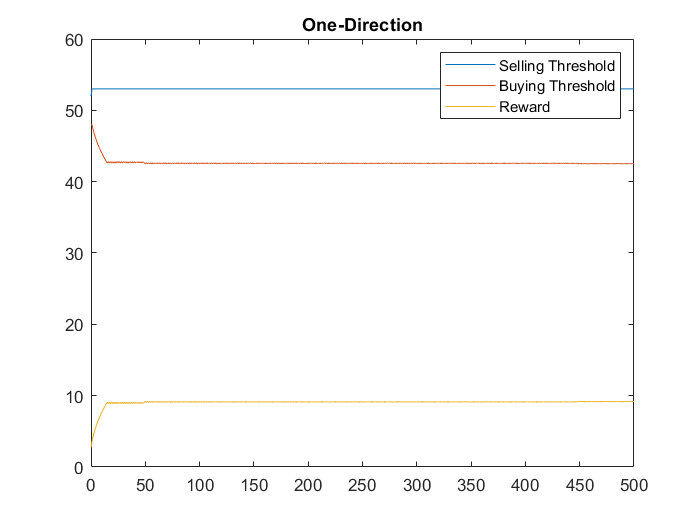


rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "One-Direction"];
for mode=0:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter
        c = (iter) ^ (-1/2);
        reward(iter) = MultiTransactionReward(stock_price, b(iter), s(iter), T, 0.0001);
        
        incre_b = b(iter) + c;
        reward_incre_b = MultiTransactionReward(stock_price, incre_b, s(iter), T, 0.0001);
        
        decre_b = b(iter) - c;
        reward_decre_b = MultiTransactionReward(stock_price, decre_b, s(iter), T, 0.0001);
        
        incre_s = s(iter) + c;
        reward_incre_s = MultiTransactionReward(stock_price, b(iter), incre_s, T, 0.0001);
        
        decre_s = s(iter) - c;
        reward_decre_s = MultiTransactionReward(stock_price, b(iter), decre_s, T, 0.0001);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    
    reward(iter + 1) = MultiTransactionReward(stock_price, b(iter + 1), s(iter + 1), T, 0.0001);
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward")
    title(strategis(mode + 1))
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
end

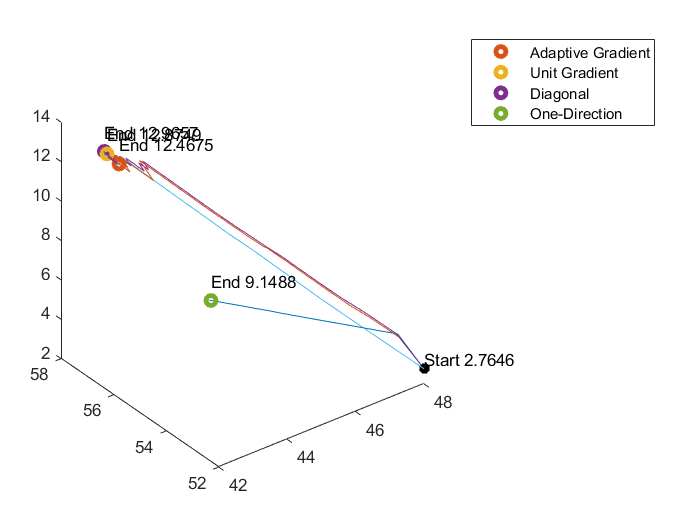

clf;
for i=1:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    text(b(end), s(end), reward(end) + 1, append('End ', string(reward(end))))
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 0.5, append('Start ', string(rewards{i}(1))))

for i=1:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i));
end
legend(p)

% Explore the surface of the reward function at all possible b and s
% b and s are the x and y axes of the plot
% and the surface (z) is the reward computed at a given (b, s)
s_all = linspace(40, 60, 500);
b_all = linspace(40, 60, 500);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T, 0.0001);
    end
end

clf;
h = surf(b_all, s_all, reward_all)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1×500 double]
           YData: [1×500 double]
           ZData: [500×500 double]
           CData: [500×500 double]

  Show all properties


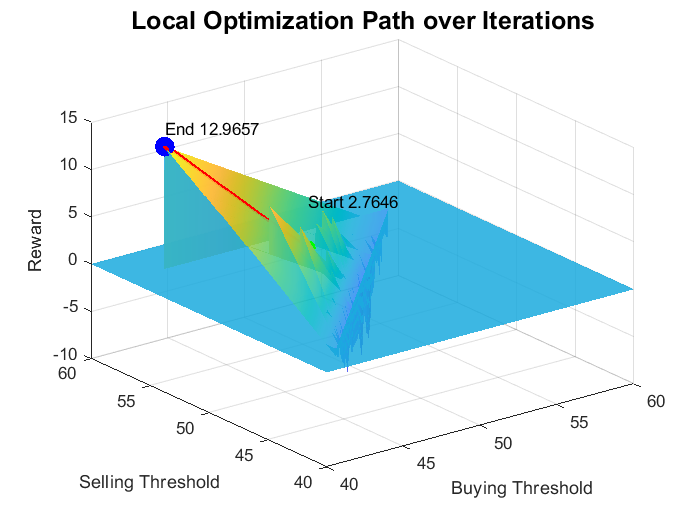

alpha 0.85
set(h,'LineStyle','none')
set(h, "FaceLighting", "none")
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
%zlim([-50, 50])
hold on

i=3;
b = b_s{i};
s = s_s{i};
reward = rewards{i};
plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
plot3(b, s, reward, 'red','linewidth',2)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
text(b(1), s(1), reward(1) + 5, append('Start ', string(reward(1))))
text(b(end), s(end), reward(end) + 2, append('End ', string(reward(end))))
title("Local Optimization Path over Iterations", "FontSize", 15)
hold off

b(end), s(end)

ans = 42.5587

ans = 57.0781

## Assess the Optimal Threshold on the Future Stock Price

clf;
real_stock_price = readmatrix("stock_prices\INTC_18_21", 'Range', 'E202:E401');
real_stock_price

real_stock_price =    45.8900
   44.9700
   44.0000
   45.0100
   44.5000
   42.4200
   44.3100
   45.6900
   45.4000
   47.7600


T = length(real_stock_price) - 1;
% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price))

times =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


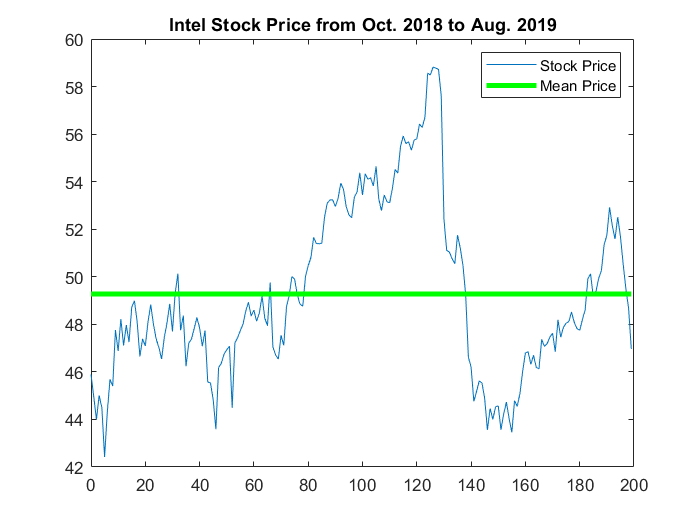

plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3)
legend("Stock Price", "Mean Price")
title("Intel Stock Price from Oct. 2018 to Aug. 2019")
hold off

t = times;

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

one_stock_price = real_stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

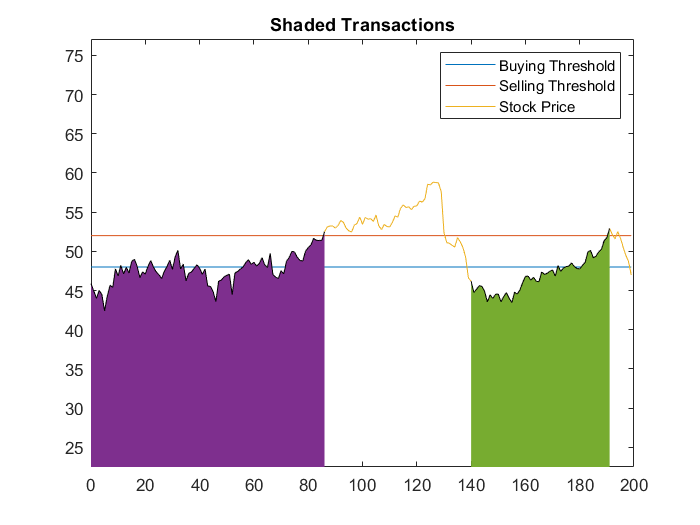

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / length(one_stock_price) * (T + 1) - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

ylim([min(stock_price - 20), max(stock_price + 20)])

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.0001 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.0001 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =     2.5611    2.7013


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 5.2624

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s
sel_mode = 2;
disp("Select " + strategis(sel_mode + 1))

Select Diagonal


b = [];
s = [];
b = b_s{sel_mode + 1};
s = s_s{sel_mode + 1};

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end));

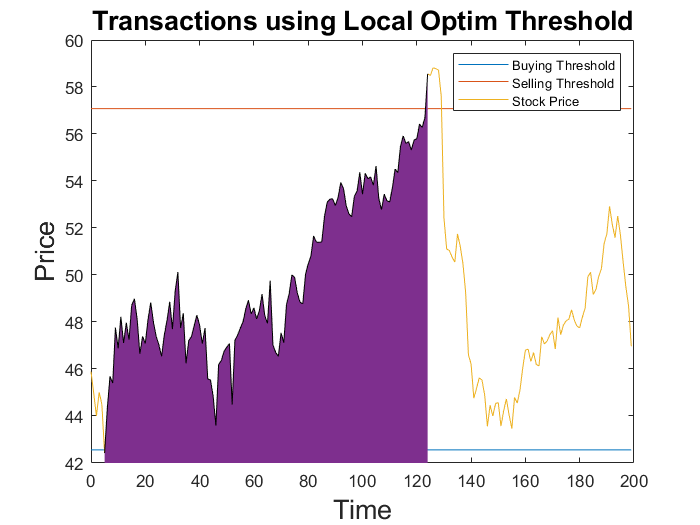

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / length(one_stock_price) * (T + 1) - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

ylim([42, 60])

legend("Buying Threshold", "Selling Threshold", "Stock Price", "FontSize", 8)
title("Transactions using Local Optim Threshold", "FontSize", 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.0001 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.0001 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi = 12.8502

disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 12.8502

## Global Optimization:

### Generate multiple possible trends of Intel stocks 

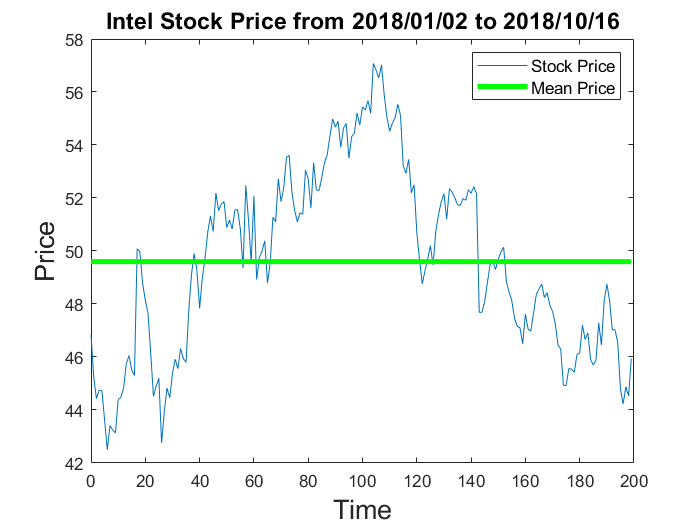

clf;
clear;
real_stock_price = readmatrix("stock_prices\INTC_18_21", 'Range', 'E2:E201');
real_stock_price;
T = length(real_stock_price) - 1;
% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3);
legend("Stock Price", "Mean Price", "FontSize", 10)
title("Intel Stock Price from 2018/01/02 to 2018/10/16", "FontSize", 14)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

clf;

NSample = 100;
N_T = 1000;
t0=0;

[TProcess, BProcess] = BrownMotion(NSample, t0, 0, T, N_T);

t0=0;
y0 = [log(real_stock_price(1))];
h = (T - t0) / N_T;

stock_prices = [];

for k=1:NSample
    w_diff = diff(BProcess(:, k));
    %w_diff = normrnd(0, sqrt(h), N_T-1);
    x_prime = @(t, y) 0.02 * (log(mean(real_stock_price)) - y(1)) + 0.06 * (w_diff(int32(t / h) + 1));
    f = {x_prime};
    
    [ymat, t] = EulerSystem(f, t0, y0, T, N_T);
    stock_prices = cat(2, stock_prices, exp(ymat(:, 1)));
    plot(t, stock_prices(:, k))
    hold on
end
p = []


p =

     []



p(1) = plot(t, ones(length(t), 1) * mean(real_stock_price),'g','LineWidth',3, 'DisplayName', "Long-term Mean")

p = 13.0001

p(2) = plot(t, ones(length(t), 1) * mean(mean(stock_prices)),'r','LineWidth',3, 'DisplayName', "Stock Price Mean")

p =    13.0001   14.0001


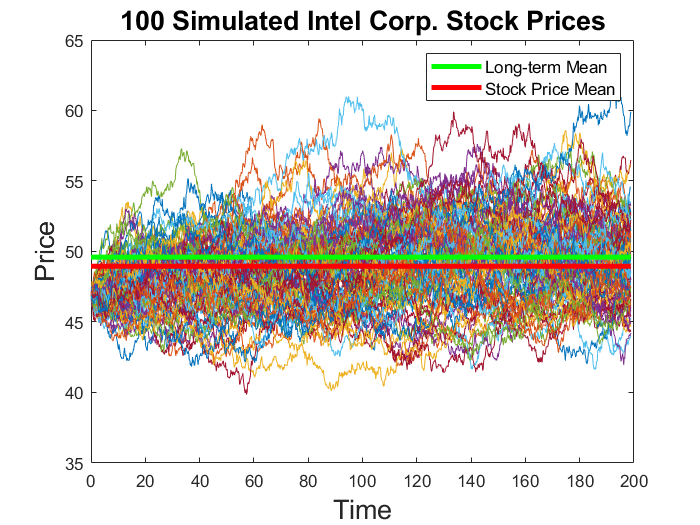

title("100 Simulated Intel Corp. Stock Prices",'FontSize', 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend(p, 'FontSize', 10)
hold off

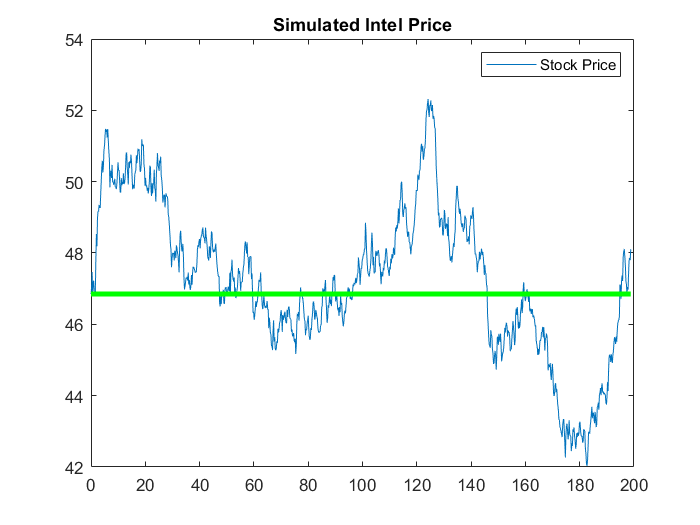

clf;
plot(t, stock_prices(:, 1))
hold on
plot(t, ones(length(t), 1) * exp(y0(1)),'g','LineWidth',3)
legend("Stock Price")
title("Simulated Intel Price")
hold off

## Start Optimizing

b0 = 48;
s0 = 52;
num_iter = 500;
mode = 2;

s = [];
b = [];
reward = [];
b(1) = b0

b = 48

s(1) = s0

s = 52

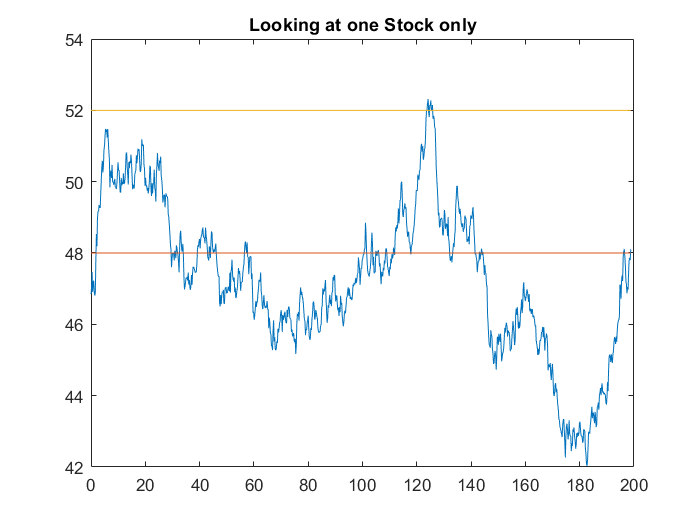

% stock_price = stock_prices(:, randi(NSample));
stock_price = stock_prices(:, 1);
clf;
plot(t, stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)
title("Looking at one Stock only")
hold off


for iter=1:num_iter
    c = (iter) ^ (-1/2);
    reward(iter) = TransactionReward(stock_prices, b(iter), s(iter), T, 0.0001);
    
    incre_b = b(iter) + c;
    reward_incre_b = TransactionReward(stock_prices, incre_b, s(iter), T, 0.0001);
    
    decre_b = b(iter) - c;
    reward_decre_b = TransactionReward(stock_prices, decre_b, s(iter), T, 0.0001);
    
    incre_s = s(iter) + c;
    reward_incre_s = TransactionReward(stock_prices, b(iter), incre_s, T, 0.0001);
    
    decre_s = s(iter) - c;
    reward_decre_s = TransactionReward(stock_prices, b(iter), decre_s, T, 0.0001);
    
    gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
    gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
    
    mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
    
    [next_b, next_s] = update_bs(b(iter), s(iter), ...
        gradient_b, gradient_s, ...
        iter, c, mode);
    
    b(iter + 1) = next_b;
    s(iter + 1) = next_s;
    
    change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
    if iter > 1 && change < 0.001
        break
    end
end
change

change = 0.0632

reward(iter + 1) = TransactionReward(stock_prices, b(iter + 1), s(iter + 1), T, 0.0001)

reward =     2.0773    2.8887    2.9863    2.9216    2.8950    2.7554    2.8430    2.8041    2.8634    2.8345    2.9287    2.9278    2.8977    2.9636    2.8712    3.0137    3.0249    3.0052    3.0314    2.9964    3.0406    3.0313    3.0485    3.0245    3.0554    3.0180    3.0616    3.0127    3.0670    3.0089    3.0720    3.0030    3.0763    2.9991    3.0803    2.9957    3.0841    2.9924    3.0875    2.9894    3.0907    2.9867    3.0937    2.9842    3.0964    3.0038    3.1043    3.0062    3.1020    3.0084


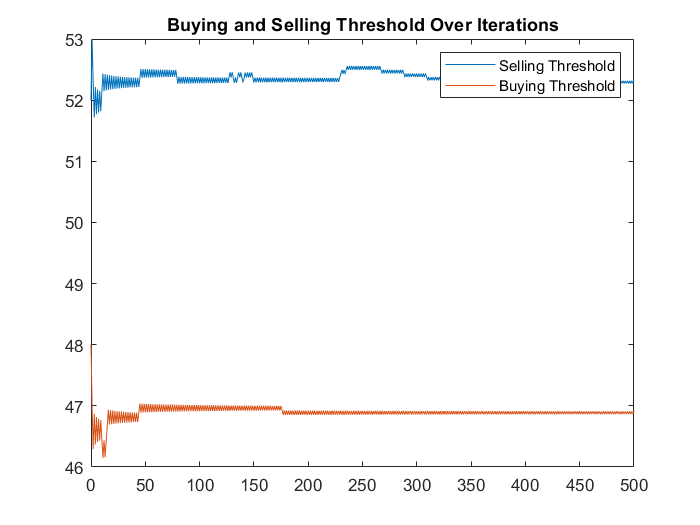

clf;
figure()
plot(linspace(0, length(reward) - 1, length(reward)), s)
hold on
plot(linspace(0, length(reward) - 1, length(reward)), b)
legend("Selling Threshold", "Buying Threshold")
title("Buying and Selling Threshold Over Iterations")
hold off

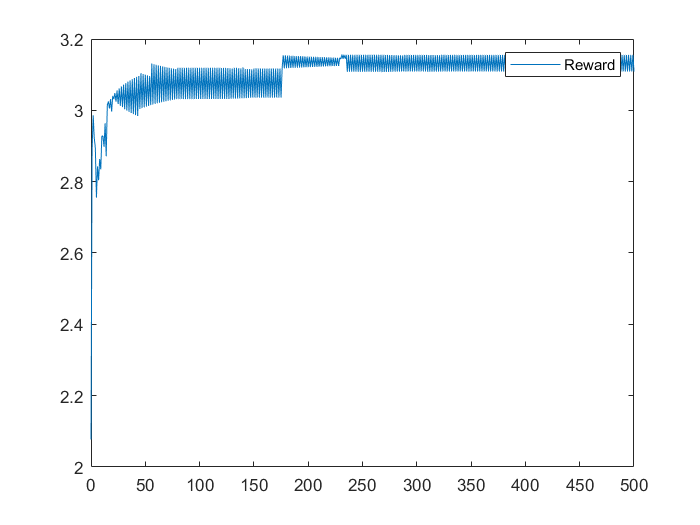

plot(linspace(0, length(reward) - 1, length(reward)), reward)
legend("Reward")
hold off

% Explore the surface of the reward function at all possible b and s
% b and s are the x and y axes of the plot
% and the surface (z) is the reward computed at a given (b, s)
s_all = linspace(40, 60, 500);
b_all = linspace(40, 60, 500);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = TransactionReward(stock_prices, b_all(i), s_all(j), T, 0.0001);
    end
end

clf;
h = surf(b_all, s_all, reward_all)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1×500 double]
           YData: [1×500 double]
           ZData: [500×500 double]
           CData: [500×500 double]

  Show all properties


alpha 0.85
set(h,'LineStyle','none')
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
%zlim([-50, 50])
hold on
p=[];
p(1) = plot3(b(1), s(1), reward(1), 'ogreen','linewidth', 3, 'DisplayName', "Start " + string(reward(1)))

p = 18.0001

plot3(b, s, reward, 'red','linewidth',2)
p(2) = plot3(b(end), s(end), reward(end), 'oblue','linewidth', 6, 'DisplayName', "End " + string(reward(end)))

p =    18.0001   19.0001


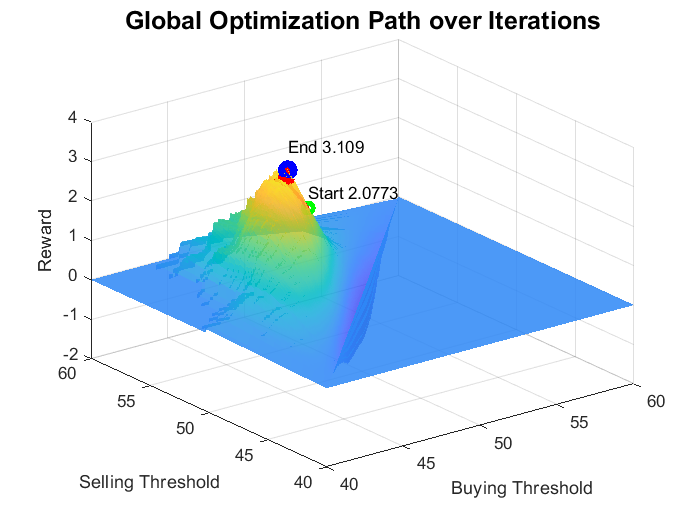

text(b(1), s(1), reward(1) + reward(1) * 0.2, append('Start ', string(reward(1))))
text(b(end), s(end), reward(end) + reward(end) * 0.2, append('End ', string(reward(end))))
% legend(p, "FontSize", 12)
title("Global Optimization Path over Iterations", "FontSize", 15)
hold off

b(end), s(end)

ans = 46.9099

ans = 52.3170

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

clf;
real_stock_price = readmatrix("stock_prices\INTC_18_21", 'Range', 'E202:E401');
real_stock_price;
T = length(real_stock_price) - 1;
% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price))

times =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


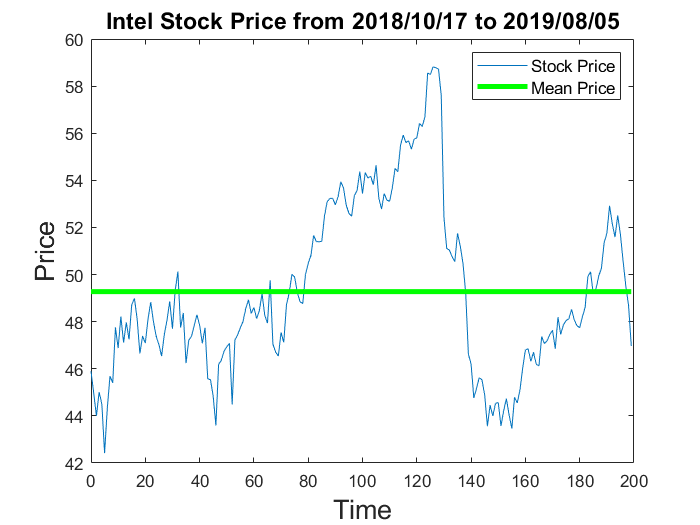

plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3)
legend("Stock Price", "Mean Price", "FontSize", 10)
title("Intel Stock Price from 2018/10/17 to 2019/08/05", "FontSize", 14)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

one_stock_price = real_stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

t = linspace(0, T, T + 1)';

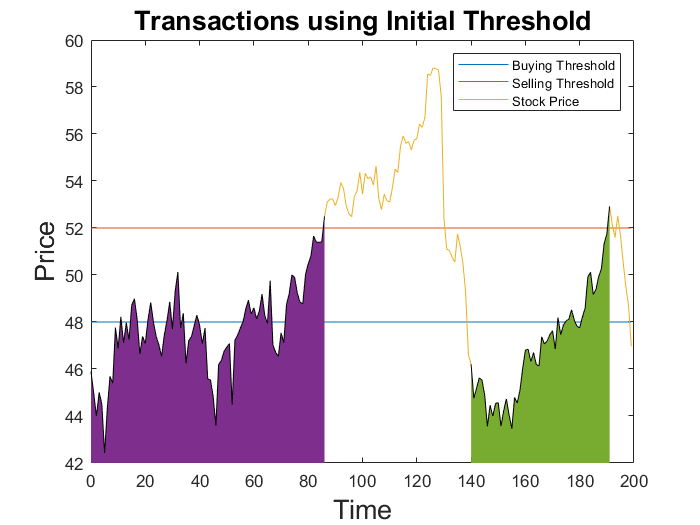

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / length(one_stock_price) * (T + 1) - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

ylim([42, 60])

legend("Buying Threshold", "Selling Threshold", "Stock Price", "FontSize", 8)
title("Transactions using Initial Threshold", "FontSize", 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.0001 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.0001 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =     2.5611    2.7013


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 5.2624

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end));

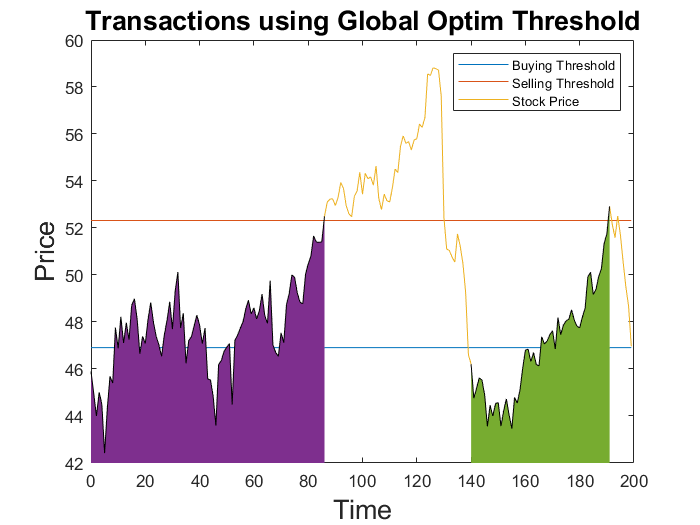

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / length(one_stock_price) * (T + 1) - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

ylim([42, 60])

legend("Buying Threshold", "Selling Threshold", "Stock Price", "FontSize", 8)
title("Transactions using Global Optim Threshold", "FontSize", 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.0001 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.0001 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi =     3.9731    4.0948


disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 8.0680

## Global + Local Optimization:

### Maximize the average reward of doing multiple transactions over a single stock price using many randomly generated stock prices

## Generate multiple possible trends of Intel stocks 

clf;
real_stock_price = readmatrix("stock_prices\INTC_18_21", 'Range', 'E2:E201');
real_stock_price;
T = length(real_stock_price) - 1;
% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price))

times =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3);
legend("Stock Price", "Mean Price")
title("Intel Stock Price from Jan. 2018 to Oct. 2018")
hold off

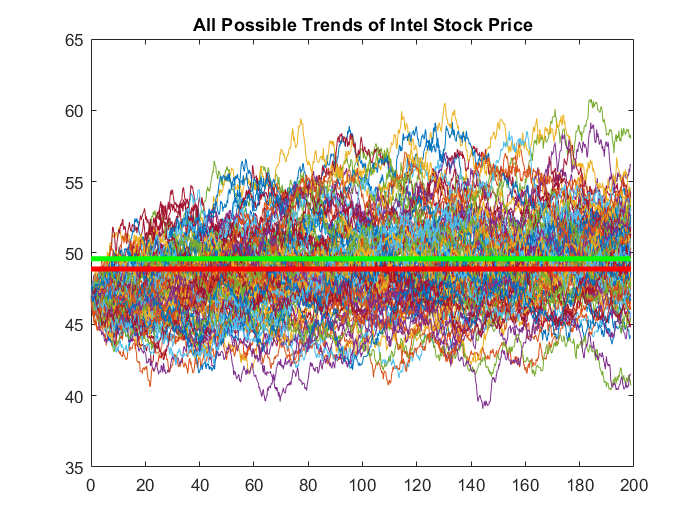

clf;

NSample = 100;
N_T = 1000;
t0=0;

[TProcess, BProcess] = BrownMotion(NSample, t0, 0, T, N_T);

t0=0;
y0 = [log(real_stock_price(1))];
h = (T - t0) / N_T;

stock_prices = [];

for k=1:NSample
    w_diff = diff(BProcess(:, k));
    %w_diff = normrnd(0, sqrt(h), N_T-1);
    x_prime = @(t, y) 0.02 * (log(mean(real_stock_price)) - y(1)) + 0.06 * (w_diff(int32(t / h) + 1));
    f = {x_prime};
    
    [ymat, t] = EulerSystem(f, t0, y0, T, N_T);
    stock_prices = cat(2, stock_prices, exp(ymat(:, 1)));
    plot(t, stock_prices(:, k))
    hold on
end

plot(t, ones(length(t), 1) * mean(real_stock_price),'g','LineWidth',3)
plot(t, ones(length(t), 1) * mean(mean(stock_prices)),'r','LineWidth',3)
title("All Possible Trends of Intel Stock Price")
hold off

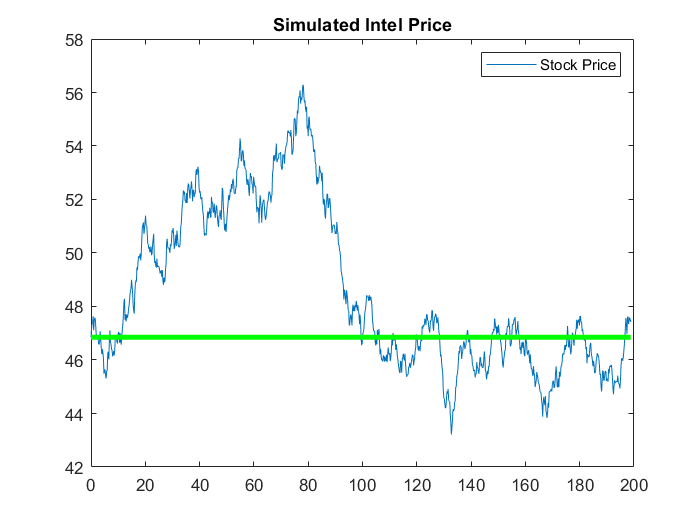

clf;
plot(t, stock_prices(:, 1))
hold on
plot(t, ones(length(t), 1) * exp(y0(1)),'g','LineWidth',3)
legend("Stock Price")
title("Simulated Intel Price")
hold off

## Start Optimizing

b0 = 48;
s0 = 52;
num_iter = 500;
mode = 2;

s = [];
b = [];
reward = [];
b(1) = b0

b = 48

s(1) = s0

s = 52

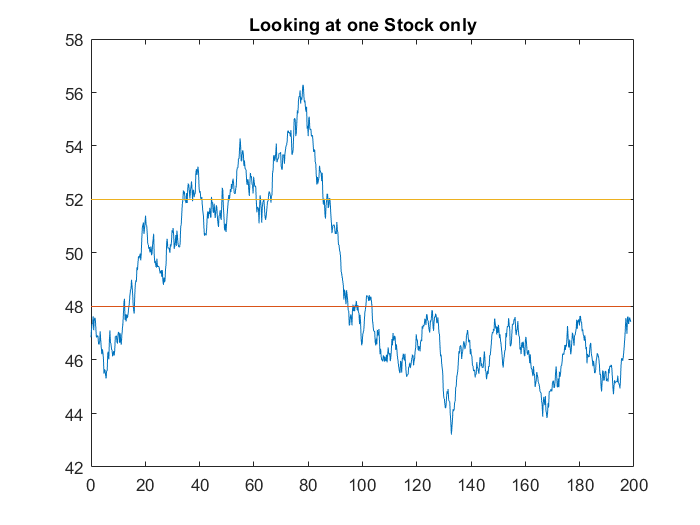

% stock_price = stock_prices(:, randi(NSample));
stock_price = stock_prices(:, 1);
clf;
plot(t, stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)
title("Looking at one Stock only")
hold off


for iter=1:num_iter
    c = (iter) ^ (-1/2);
    reward(iter) = GlobalLocalTransactionReward(stock_prices, b(iter), s(iter), T, 0.0001);
    
    incre_b = b(iter) + c;
    reward_incre_b = GlobalLocalTransactionReward(stock_prices, incre_b, s(iter), T, 0.0001);
    
    decre_b = b(iter) - c;
    reward_decre_b = GlobalLocalTransactionReward(stock_prices, decre_b, s(iter), T, 0.0001);
    
    incre_s = s(iter) + c;
    reward_incre_s = GlobalLocalTransactionReward(stock_prices, b(iter), incre_s, T, 0.0001);
    
    decre_s = s(iter) - c;
    reward_decre_s = GlobalLocalTransactionReward(stock_prices, b(iter), decre_s, T, 0.0001);
    
    gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
    gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
    
    mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
    
    [next_b, next_s] = update_bs(b(iter), s(iter), ...
        gradient_b, gradient_s, ...
        iter, c, mode);
    
    b(iter + 1) = next_b;
    s(iter + 1) = next_s;
    
    change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
    if iter > 1 && change < 0.001
        break
    end
end
change

change = 0.0632

reward(iter + 1) = GlobalLocalTransactionReward(stock_prices, b(iter + 1), s(iter + 1), T, 0.0001)

reward =     2.7077    3.3867    3.0690    3.7092    3.1914    3.6394    3.3090    3.5257    3.3803    3.6611    3.4645    3.5784    3.6067    3.6000    3.6388    3.5761    3.6679    3.5898    3.7058    3.6014    3.7388    3.5773    3.7204    3.6114    3.7202    3.6118    3.7410    3.6185    3.7838    3.6244    3.7784    3.5960    3.7735    3.6010    3.7686    3.6291    3.7684    3.6141    3.7645    3.6179    3.7610    3.6214    3.7578    3.6254    3.7547    3.6285    3.7518    3.6314    3.7491    3.6341


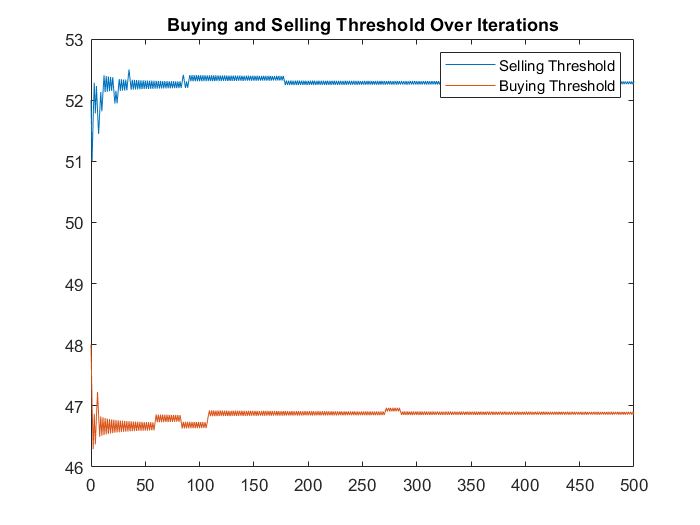

clf;
figure()
plot(linspace(0, length(reward) - 1, length(reward)), s)
hold on
plot(linspace(0, length(reward) - 1, length(reward)), b)
legend("Selling Threshold", "Buying Threshold")
title("Buying and Selling Threshold Over Iterations")
hold off

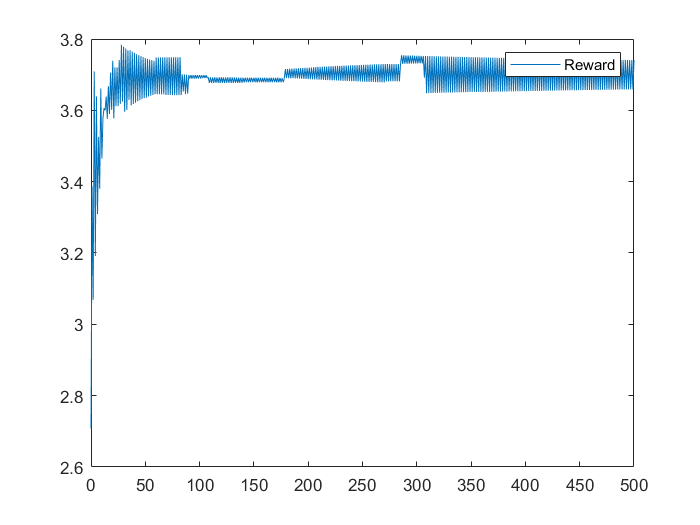

plot(linspace(0, length(reward) - 1, length(reward)), reward)
legend("Reward")
hold off

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

clf;
real_stock_price = readmatrix("stock_prices\INTC_18_21", 'Range', 'E202:E401');
real_stock_price;
T = length(real_stock_price) - 1;
% len = linspace(0, length(real_stock_price) - 1, length(real_stock_price));
% 
% times = linspace(0, length(real_stock_price) - 1, N_T);
% real_stock_price = interp1(len, real_stock_price, times)';
times = linspace(0, length(real_stock_price) - 1, length(real_stock_price))

times =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


plot(times, real_stock_price)
hold on
plot(times, ones(length(times), 1) * mean(real_stock_price, 'all'),'g','LineWidth',3)
legend("Stock Price", "Mean Price")
title("Intel Stock Price from Oct. 2018 to Aug. 2019")
hold off

one_stock_price = real_stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

t = linspace(0, T, T + 1)';

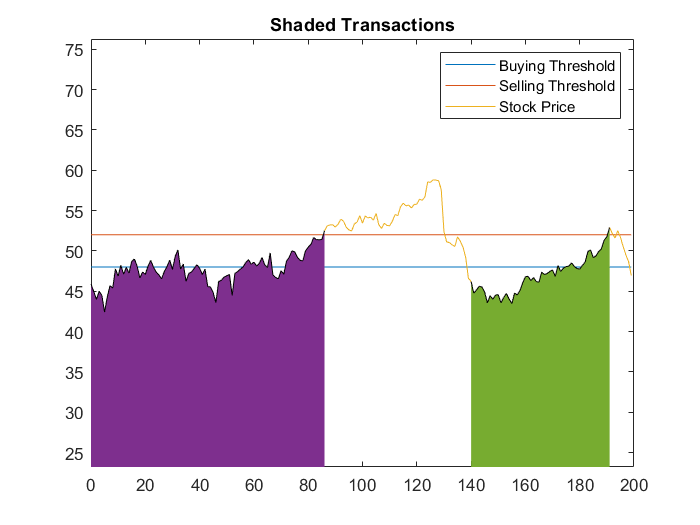

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / length(one_stock_price) * (T + 1) - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

ylim([min(stock_price - 20), max(stock_price + 20)])

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.0001 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.0001 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =     2.5611    2.7013


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 5.2624

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end));

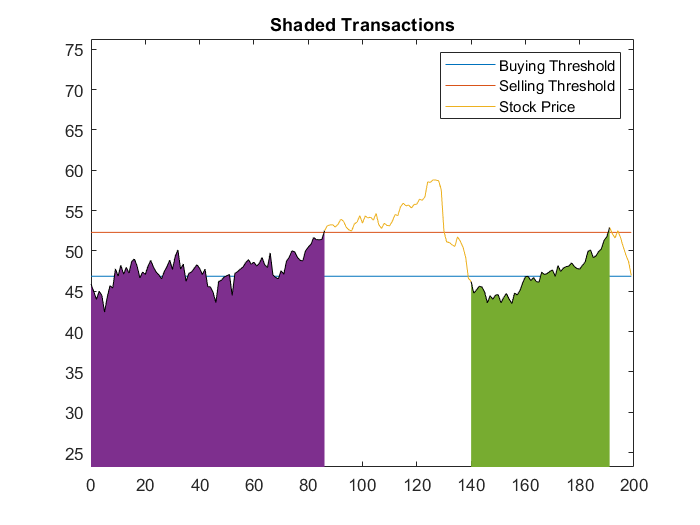

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / length(one_stock_price) * (T + 1) - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

ylim([min(stock_price - 20), max(stock_price + 20)])

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.0001 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.0001 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi =     4.0154    4.1365


disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 8.1519

## Function Definitions:

function [ymat, t]=EulerSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N
        for i=1:length(y0)
            ymat(j, i) = ymat(j - 1,i) + h * f{i}(t(j-1), ymat(j - 1, :));
            t(j) = t(j - 1) + h;
        end
    end
end


function [ymat, t]=RKSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N
        for i=1:length(y0)
            k1 = h * f{i}(t(j-1), ymat(j - 1, :));
            k2 = h * f{i}(t(j-1) + h, ymat(j - 1, :) + k1);
            ymat(j, i) = ymat(j - 1,i) + (1 / 2) * (k1 + k2);
            t(j) = t(j - 1) + h;
        end
    end
end


function [TProcess, BProcess]=BrownMotion(sample, t0, y0, b, N)
    BProcess = [];
    TProcess = [];
    NSample = sample;
    N_T = N;
    T = b;
    
    for k = 1:NSample
        B = y0;
        t = t0;
        BProcess(1,k)=B; TProcess(1,k)=t;
        for i=2:N_T
            dt =  T/N_T;
            t = t + dt;
            B = B + sqrt(dt)*randn(1); %increments in B are normally distibuted with variance dt
            BProcess(i,k) = B;
            TProcess(i,k) = t;
        end
    end
end


function [next_b, next_s] = update_bs(b, s, gradient_b, gradient_s, ...
    iter, c, mode)
    eps =0.000001;
    % Update strategy 0 gradient vector
    if mode == 0
        next_b = b + gradient_b / iter;
        next_s = s + gradient_s / iter;
    % Update strategy 1 unit vector
    elseif mode == 1
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        next_b = b + gradient_b / (mag + eps) * c;
        next_s = s + gradient_s / (mag + eps) * c;
    % Update strategy 2 move in diagonal 
    elseif mode == 2
        if gradient_b > 0
            next_b = b + c;
        else
            next_b = b - c;
        end
        
        if gradient_s > 0
            next_s = s + c;
        else
            next_s = s - c;
        end
    % Update strategy 3 move in largest gradient (eithr b or s)
    elseif mode == 3
        if abs(gradient_s) > abs(gradient_b)
            next_b = b;
            if gradient_s > 0
                next_s = s + c;
            else
                next_s = s - c;
            end
        else
            next_s = s;
            if gradient_b > 0
                next_b = b + c;
            else
                next_b = b - c;
            end
        end
    end
end


function [buy_times, sell_times]=find_set_of_selling_buying_time(one_stock_price, b, s)
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    return
                end
                if prev_s > length(tau_s)
                    return
                end
                i = RowNrs(1);
                break
            end
        end
        i = i + 1;
    end
end


% Global Optimization
% Optimize on one transaction of multiple different stock prices
function reward=TransactionReward(stock_prices, b, s, T, rho)
    if b > s
        reward = 0;
        return
    end
    phi = [];
    for k=1:length(stock_prices(1, :))
        [tau_b,ColNrs] = find(stock_prices(:, k) < b);
        [tau_s,ColNrs] = find(stock_prices(:, k) > s);
        if length(tau_b) < 1
            continue
        end
        [tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));
        if length(tau_s) < 1
            continue
        end
        tau_b = tau_b(1);
        phi(k) = exp(-rho * tau_s / length(stock_prices) * T) * s * (1 - 0.01) - exp(-rho * tau_b / length(stock_prices) * T) * b * (1 + 0.01);
    end
    
    if length(phi) < 1
        reward = 0;
    else
        reward = sum(phi) / length(stock_prices(1, :));
    end       
end


% Local Optimization
% Optimize on multiple transaction of one randomly chosen stock
function reward=MultiTransactionReward(one_stock_price, b, s, T, rho)
    if b > s
        reward = 0;
        return
    end
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        RowNrs = [];
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    break
                end
                if prev_s > length(tau_s)
                    break
                end
                i = RowNrs(1);
                break
            end
        end
        if length(RowNrs) < 1 
            break
        end
        if prev_s > length(tau_s)
            break
        end
        i = i + 1;
    end
    
    tau_b = buy_times;
    tau_s = sell_times;
    
    if length(tau_b) < 1
        reward = 0;
    else
        phi = exp(-rho * tau_s / length(one_stock_price) * T) * s * (1 - 0.01) - exp(-rho * tau_b / length(one_stock_price) * T) * b * (1 + 0.01);
        reward = sum(phi);
    end
end


function reward=GlobalLocalTransactionReward(stock_prices, b, s, T, rho)
    if b > s
        reward = 0;
        return
    end
    
    phi = [];
    for k=1:length(stock_prices(1, :))
        phi(k) = MultiTransactionReward(stock_prices(:, k), b, s, T, rho);
    end
    
    if length(phi) < 1
        reward = 0;
    else
        reward = sum(phi) / length(stock_prices(1, :));
    end       
end